# **ME: 6420 Short Homework #3**

**Due 3/17/21**

**Motion and Measurement Models**

### **By: Michael Swafford**

Let's assume we have velocity data for a simple collaborative robot designed to assist with upper extremity rehabilitation following a stroke. Specifically, the robot was deisng to assist a person in moving their hand in the horizontal plane with their affected arm across their body away from their should.

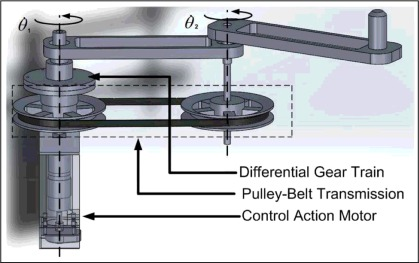

The provided MATLAB data file provides truth position (**p**), acceleration (**a**), and jerk (**j**) data as well as measured velocity (**v**) of their hand and the time vector (**t**) for the dataset. Assume the velocity is corrupted by zero mean Gaussian measurement noise and a bias that we will assume is constant and deterministic (in reality, it should be a random walk but let's keep it simple)

# 1) First, let's assume that the controller for the system was specifically designed to regulate the postion of the cobot. **Calculate the numerical integral of the data in the file. Plot the result and the truth position data and comment on how they compare.**

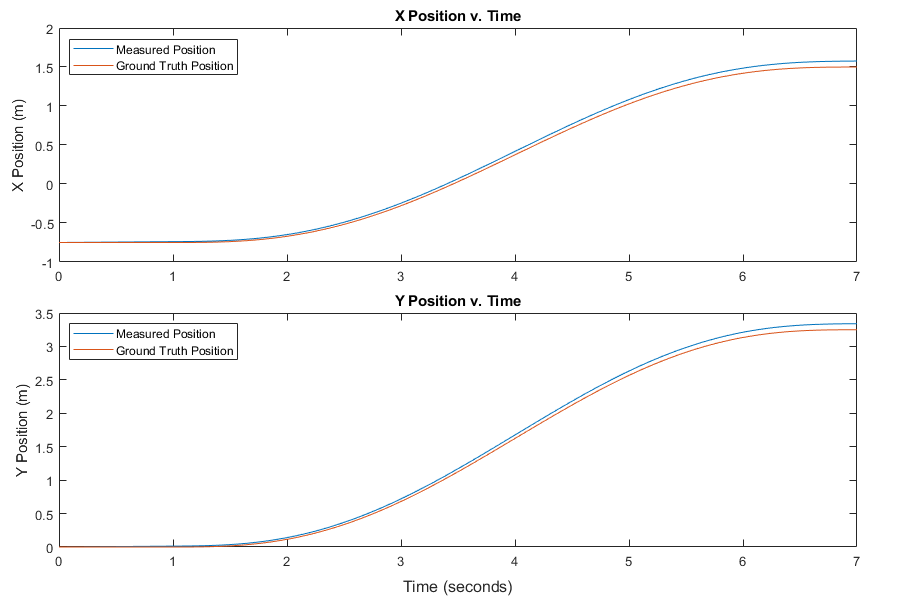

load("data (1).mat")

%let's put everything into a structure to make our life easier
data.a.x = a(:,1);
data.a.y = a(:,2);
data.j.x = j(:,1);
data.j.y = j(:,2);
data.p.x = p(:,1);
data.p.y = p(:,2);
data.time = t;
data.v.x = v(:,1);
data.v.y = v(:,2);
clear a j p t v %get rid of duplicate variables

%initial conditions
initial_x = data.p.x(1,1);
initial_y = data.p.y(1,1);

%integrate the data
measuredPositionX = cumtrapz(data.time,data.v.x)+initial_x;
measuredPositionY =  cumtrapz(data.time,data.v.y)+initial_y;



figure("Position",[10,11, 900,600])
t=tiledlayout(2,1);
t.Padding = "compact";
t.TileSpacing = 'compact';
xlabel(t,'Time (seconds)');
ax1 =  nexttile;
plot(ax1,data.time,measuredPositionX);
hold on
plot(data.time,data.p.x);
hold off
title(ax1,"X Position v. Time")
ylabel(ax1,"X Position (m)")
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')
ax2=nexttile;
plot(ax2,data.time,measuredPositionY);
hold on
plot(ax2,data.time,data.p.y);
hold off
title(ax2,"Y Position v. Time")
ylabel(ax2,"Y Position (m)")
legend(["Measured Position","Ground Truth Position"],"Location",'northwest')

### Comparing the results, the measured x-position data has a constant bias approximately 3/4 of a meter postivie to the ground truth data. The Y-position measured data appears to have no bias, but has drift to the negative over time. Likely due to some increasing level of noise and therefore variance.

# **2) Now, use the t = [0,1] seconds of data to estimate the velocity sensor's bias. Specifically, use an MLE approach. Assuming the bias is deterministic, recalculate the numerical integral of the bias-corrected data using the same approach from question 1. Again plot the result,and comment. Comment on what trend you would expect for doing the same numerical integration for a much longer data collection. **

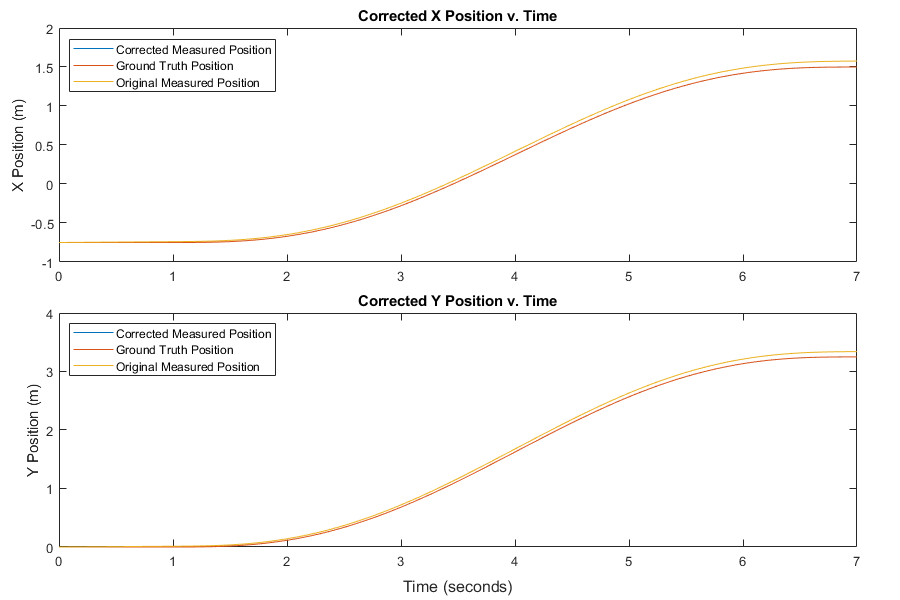

sampleRate = 1/(data.time(end)/length(data.time));
v2x = data.v.x(1:sampleRate); %extract first 1 second of x vel data
v2y = data.v.y(1:sampleRate);
v2x_mle = mle(v2x);
v2y_mle = mle(v2y);


measuredPositionXCorr = cumtrapz(data.time,data.v.x-v2x_mle(1,1))+initial_x;
measuredPositionYCorr = cumtrapz(data.time,data.v.y-v2y_mle(1,1))+initial_y;
figure("Position",[10 10 900 600])
t = tiledlayout(2,1);
t.Padding = "compact";
t.TileSpacing = 'compact';
xlabel(t,'Time (seconds)');
ax1 = nexttile;
plot(ax1,data.time,measuredPositionXCorr);
hold on
plot(ax1,data.time,data.p.x);
plot(ax1,data.time,measuredPositionX)
hold off
title("Corrected X Position v. Time")
ylabel("X Position (m)")
legend(["Corrected Measured Position","Ground Truth Position","Original Measured Position"],"Location",'northwest');
ax2 = nexttile;
plot(ax2,data.time,measuredPositionYCorr);
hold on
plot(ax2,data.time,data.p.y);
plot(ax2,data.time,measuredPositionY)
hold off
title("Corrected Y Position v. Time")
ylabel("Y Position (m)")
legend(["Corrected Measured Position","Ground Truth Position","Original Measured Position"],"Location",'northwest');

### **Results compare much better to the ground truth now that the bias has been accounted for. For a longer time series we'd expect to see some drift in the data over time since the bias isn't truely deterministic.**

# **3) Now, let's assume that the controller for the cobot regulates the position of the system by minimizing jerk (derivative of position) to ensure the end effector's trajectory is as smooth as possible. Calculate the numerical derivative of the data in the file twice (you can use a function like gradient). Plot the results with their corresponding turth data and comment on how they compare.**

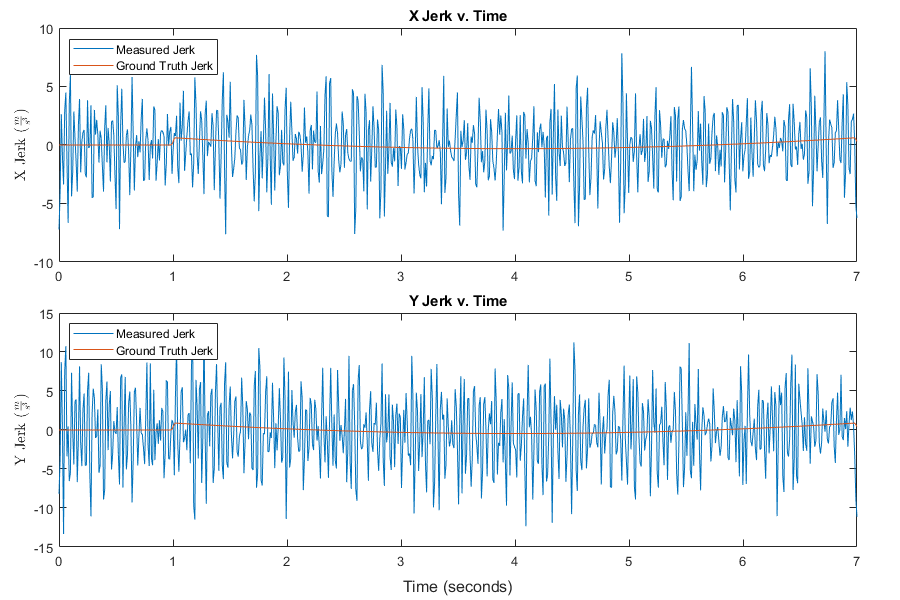

measuredJerkX = gradient(data.v.x,1/sampleRate);
measuredJerkY = gradient(data.v.y,1/sampleRate);
measuredJerkX = gradient(measuredJerkX,1/sampleRate);
measuredJerkY = gradient(measuredJerkY,1/sampleRate);

figure("Position",[10,11, 900,600])
t=tiledlayout(2,1);
t.Padding = "compact";
t.TileSpacing = 'compact';
xlabel(t,'Time (seconds)');
ax1 =  nexttile;
plot(ax1,data.time,measuredJerkX);
hold on
plot(data.time,data.j.x);
hold off
title(ax1,"X Jerk v. Time")
ylabel(ax1,"X Jerk ($\frac{m}{s^3}$)",'Interpreter',"latex")
legend(["Measured Jerk","Ground Truth Jerk"],"Location",'northwest')
ax2=nexttile;
plot(ax2,data.time,measuredJerkY);
hold on
plot(ax2,data.time,data.j.y);
hold off
title(ax2,"Y Jerk v. Time")
ylabel(ax2,"Y Jerk ($\frac{m}{s^3}$)",'Interpreter',"latex")
legend(["Measured Jerk","Ground Truth Jerk"],"Location",'northwest')

### **Measured jerk is very noisy due to derivative math from velocity. A moving average could maybe help to clean this noise or a high-pass filter.**

## ** In many dynamic state estimation problems, the noise characteristics are linearized such that we can use the resulting Gaussian covariance matrix thereby greatly simplifying much of the math. Let's consider the case where we have a stationary robot with a sensor capable of observing range and bearing to nearby landmarks. We will specifically focus on the case where the range data are fairly accurate, but the bearing data are considerably noisier. We are interested in extracting the Cartesian position of the landmark based on observations obtained by the robot at the origin. Suppose we make (range, bearing) observations with mean (10,0m, 0 radians) and standard deviation (0.5, 0.25 radians). Assume the measurement noises are Gaussian and independent.**

# **4) Generate a point cloud with 10,000 samples from the distribution described in the prompt over the position of the landmark in the sensor frame and the Cartesian frame. In other words, generate a set of observations of (range,bearing) and convert these points into (x,y) coordinates. Provide a plot (with labels and units) and comment on the resulting shape of the point cloud.**

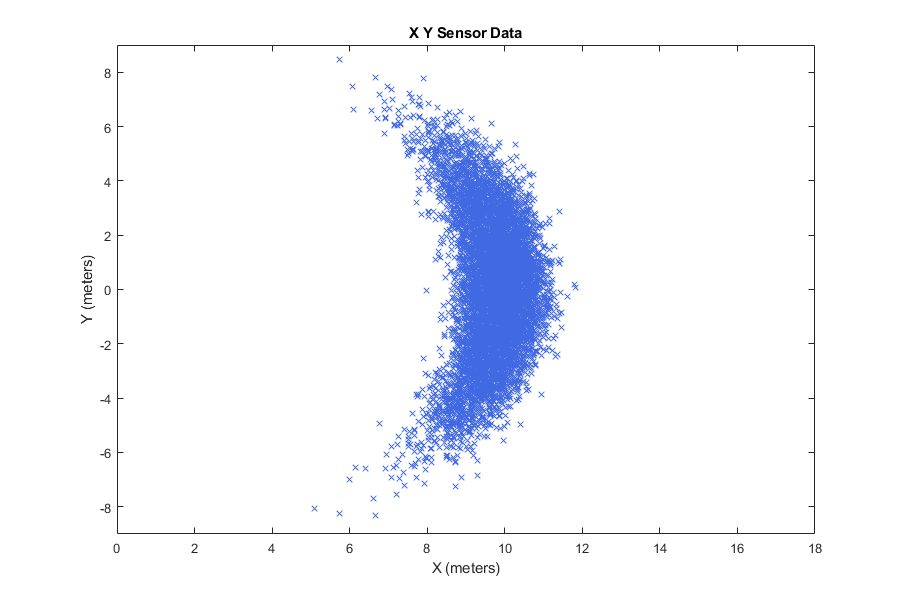

MEAN = [10,0]; %range and bearing means
sigma = [0.5,0.25]; %range and bearing stdev
range = normrnd(MEAN(1,1),sigma(1,1),[1,10000]);
bearing = normrnd(MEAN(1,2),sigma(1,2),[1,10000]);

%convert from polar
[rangeXY, bearingXY] = pol2cart(bearing,range);

figure('Position',[10 10 900 600]);
plot(rangeXY,bearingXY,'x','color','#4169E1') %royal blue
title("X Y Sensor Data")
xlabel("X (meters)")
ylabel("Y (meters)")
xlim([0 18])
ylim([-9 9])

### Point cloud shape is a boomerang that is located at a mean radial distance of 10 m from the sensor. Most of the data is tighly bound in the x=[8,10] and y=[-4,4] area.

# 5) What is the linearized covariance of the landmark position in Cartesian coordinates? **Write the Cartesian covariance in terms of the sensor covariance. **The transformation is non-linear, so you will need to compute the Jacobian of the transformation function (evaluated at the expected value for each variable) and use that to perform a similarity transformation on the sensor covariance. 

### 
$$\pmatrix{x & y} = \pmatrix{Rcos(B) & RSin(B)}$$


### 
$$J = \pmatrix{\frac{\partial}{\partial R}cos(B)R & \frac{\partial}{\partial B}cos(B)R\cr \frac{\partial}{\partial R}sin(B)R & \frac{\partial}{\partial B}sin(B)R }$$


### $cov_{cart}=J*\sigma$, where $\sigma=[0.5,0.25]^T$

J = [cos(MEAN(1,2)) -sin(MEAN(1,2))*MEAN(1,1);sin(MEAN(1,2)) cos(MEAN(1,2))*MEAN(1,1)];
covCart = J.*sigma

covCart =     0.5000         0
         0    2.5000


### The Cartesian covariance is $\pmatrix{0.5 & 0\cr 0 &2.5}$m

# 6) Use the **draw_ellipse** function provided with the homework to plot the contours of the analytical (linearized) covariance ellipses, super-imposed over the point cloud generated in the first part. Now, calculate the mean and covariance for the point clouds and use those sample-based values to plot the actual covariance ellipses. Do the linearized contour agree with the sample-based contours? Why or why not?

muXY = zeros(1,2);
muXY(1,1) = mean(rangeXY)

muXY =     9.6884         0


muXY(1,2) = mean(bearingXY)

muXY =     9.6884    0.0171


sigmaXY = cov(rangeXY,bearingXY)

sigmaXY =     0.4181   -0.0393
   -0.0393    5.9068


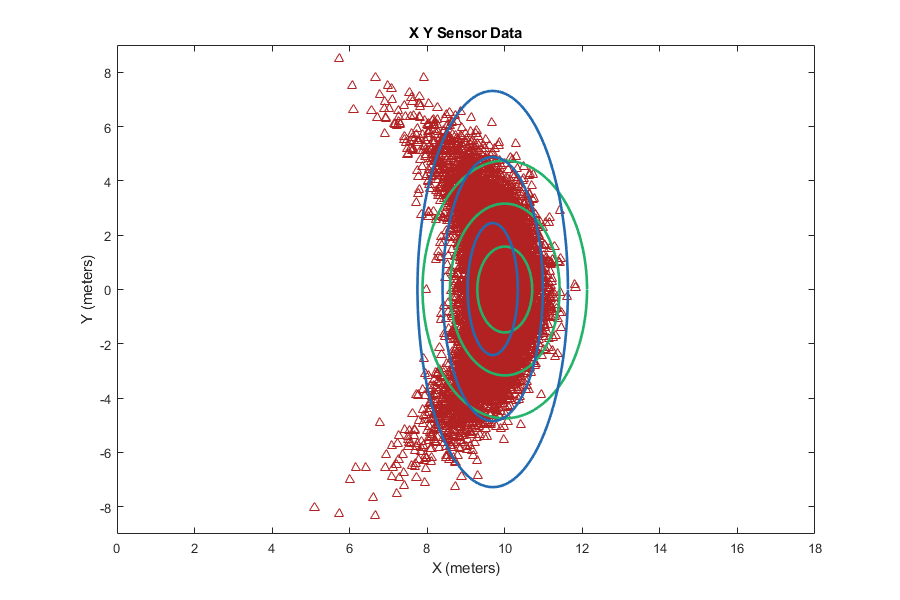


figure("Position",[10 10 900 600])
plot(rangeXY,bearingXY,'^','Color','#b22222') %Fire Brick
title("X Y Sensor Data")
xlabel("X (meters)")
ylabel("Y (meters)")
%ensure 1:1 axes scale
ylim([-9 9])
xlim([0 18])
hold on
draw_ellipse(MEAN,covCart,'#22b26a')
draw_ellipse(muXY,sigmaXY,'#226ab2')
hold off

### No the linearized contours do not agree with the sample-based contours. Likely because the true nonlinearity of the transform between polar and carteisan in this sense is not being accuratly represented when the bearing angle grows large, so the variance in that direction (really the covariance portion of sigma) is underestimated. 

## These final questions are to show the progress made towards your final project.

# The project I am proposing is a radar and stereo computer vision fusion process for SLAM in Autonomous Vehicle Applications.

# 7) What kind of data are you going to use for the mechanical system that you chose.

### There is a data set called 'nuScenes' from Motional that is open source. Contains 1000 20 second scenes with 5 available radars, 6 available cameras, an IMU and GPS , Detailed map information (for ground truth)

#  8) Provide a process model that describes how your system's states change through time. The model can be either continous or discrete. Include a process noise term and a short discussion of what types of noise that term will be encompassing.

### Choose a discrete general case SLAM process model

### $x_t = $ vehicle state matrix; $x_{1:t} = $ encompasses the vehicle path

### $m_t = $ environment landmarks from the map

### $u_t=$ control input vector; $u_{1:t}=$ sequence of inputs

### $z_t = $ sensor observations; includes radar, camera, and IMU data; $z_{1:t} = $ sequence of measurements

### Probability of state:

### $P(x_{t}|z_{1:t},u_{1:t},m_t)=\sum_{m_{t-1}}P(z_t|x_t,m_t,u_{1:t})\sum_{x_{t-1}}P(x_t|x_{t-1})P(x_{t-1}|m_t,z_{1:t-1},u_{1:t})$, probability of current state given the sequence of sensor measurements, control input and the current observable landmarks from the map

### Probability of map:

### $P(m_t|x_t,z_{1:t},u_{1:t})=\sum_{x_t}\sum_{m_t}P(m_t|x_t,m_{t-1},z_t,u_{1:t})P(m_{t-1},x_t|z_{1:t-1},m_{t-1},u_{1:t})$, probability of current map given the state, sensor measurements, and control input

### Proposed Process model:

### $\tilde x_{t+1}=f(\tilde x_t ,u_t) + \tilde W_t$; where $\tilde W_t$ is the process noise composed of gaussian movement (input) noise and numerical calculation noise (e.g integration, derivatives). $f(.)$ is governed by the nonlinear bicycle car model:

### 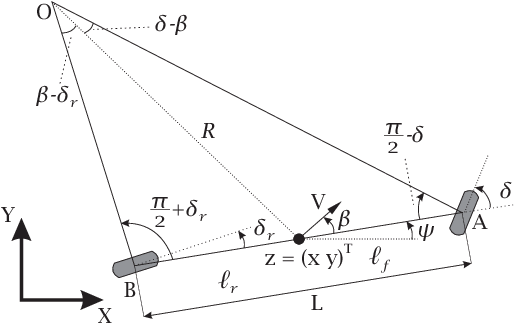 

# 9) Provide a measurement model that describes how the measurements relate to the states your described int he previous question. Include a measurement noise term.

### $\tilde z_t = g(\tilde x_t, \tilde m_t) +\tilde V_t$; where $\tilde V_t$ is composed of several measurement noises:

- radar clutter (unknown distribution)

- radar echo / mirrors (unknown distribution)

- noise in image data due to low-light (possibly gaussian)

- IMU measurement nosie (gaussain) (low-pass filter may remove more obvious vibrations)